# MAS416 test prep tutorial 1

clc; clear all; close all;

## Problem 1a)

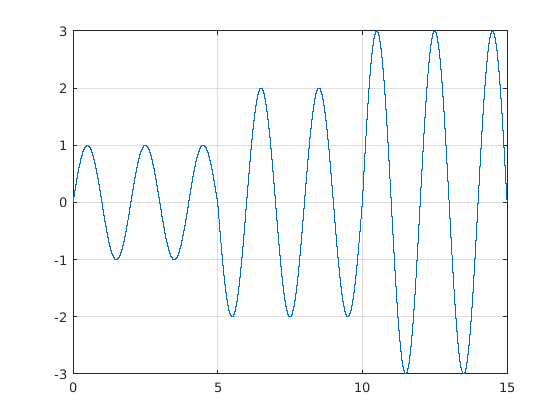

f = 0.5; % Hz
simTime = 15; % s

t = 0; % s
dt = 10^-4;
idx = 1; % counter

while(t < simTime)

    if(t <= 5)
        A = 1;
    elseif(t <= 10)
        A = 2;
    else
        A = 3;
    end
    
    y = A * sin(2*pi*f*t);
    
    t_plot(idx) = t;
    y_plot(idx) = y;

    t = t + dt;
    idx = idx + 1;

end

plot(t_plot, y_plot)
grid


y_rms = rms(y)

y_rms =       2.03778509385556e-10


## Problem 1b)

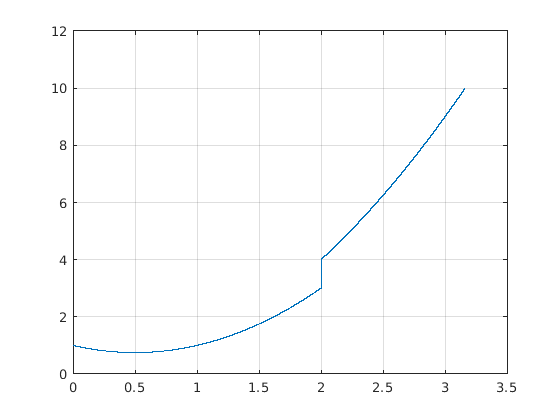

clear all;

A = 1;

yMax = 10;

t = 0; % s
dt = 10^-4;
idx = 1; % counter

y = 0; % Init y

while(y <= yMax)
    if(t <= 2)
        B = 1-t;
    else
        B = 0;
    end

    y = A*t^2 + B;

    t_plot(idx) = t;
    y_plot(idx) = y;

    t = t + dt;
    idx = idx + 1;
end

plot(t_plot, y_plot)
grid

## Problem 2a)

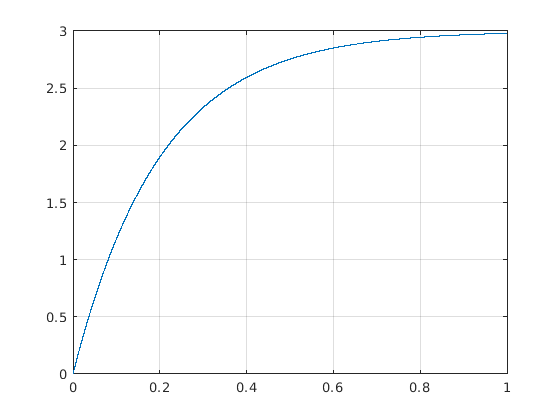

clear all;

t = 0; % s
dt = 10^-4;
idx = 1; % counter

simTime = 1; % s
y = 0;

while(t <= simTime)
    
    yDot = (3-y)/(0.2);

    t_plot(idx) = t;
    y_plot(idx) = y;

    y = y + yDot * dt;

    t = t + dt;
    idx = idx + 1;
end

plot(t_plot, y_plot)
grid

## Problem 2b)

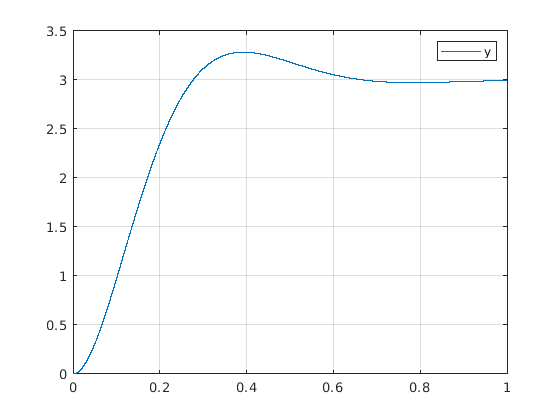

clear all;

t = 0; % s
dt = 10^-4;
idx = 1; % counter

simTime = 1; % s
y = 0;
yDot = 0;

while(t <= simTime)
   
    yDotDot = 100 * (3-y)-12*yDot;

    t_plot(idx) = t;
    y_plot(idx) = y;
    yDot_plot(idx) = yDot;

    yDot = yDot + yDotDot*dt;
    y = y + yDot*dt;

    t = t + dt;
    idx = idx + 1;

end

plot(t_plot, y_plot)
legend("y")
grid
hold off

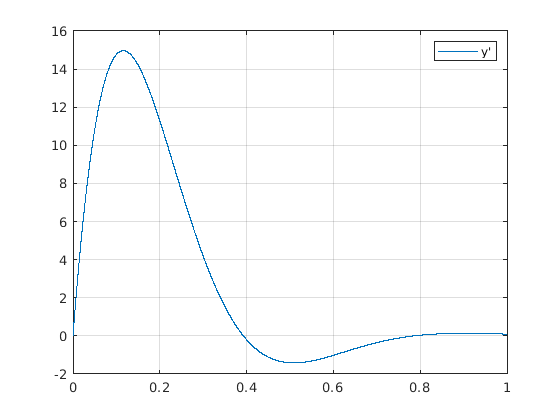

plot(t_plot, yDot_plot)
legend("y'")
grid

## Problem 3

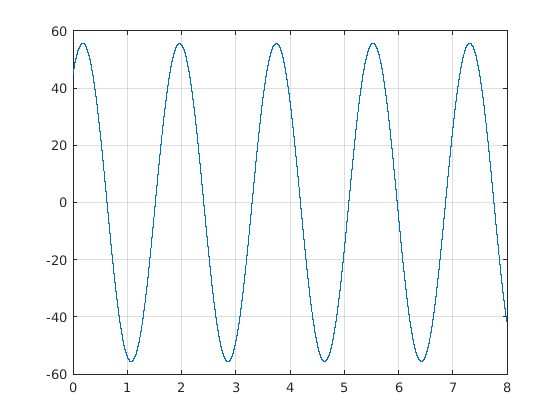

clear all;

L = 0.7; % m
m = 24; % kg
g = 9.81; % m/s^2
theta = deg2rad(45); % rad
thetaDot = 2; % rad/s

simTime = 8; % s
t = 0; % s
dt = 10^-4; % s
idx = 1; % counter

while(t <= simTime)
    thetaDotDot = -g/L * sin(theta);

    t_plt(idx) = t;
    y_plt(idx) = theta;

    thetaDot = thetaDot + thetaDotDot*dt;
    theta = theta + thetaDot*dt;

    t = t + dt;
    idx = idx + 1;
end

plot(t_plt, rad2deg(y_plt))
grid

## Problem 4

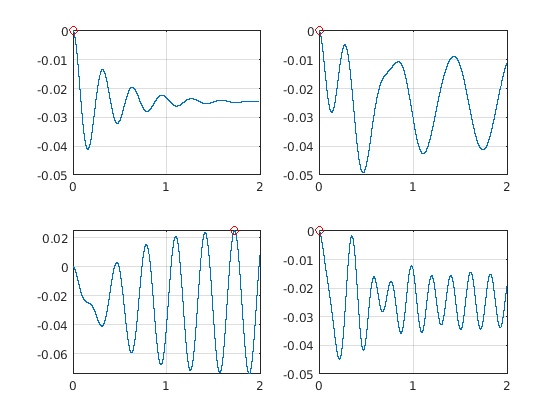

clear all;

t = 0; % s
dt = 10^-5; % s
idx = 1; % counter
simTime = 2; % s

m = 100; % kg
g = 9.81; % m/s^2
k = 40*10^3; % N/m
c = 500; % Ns/m
y = 0;
yDot = 0;

for i = 1:4
    while(t <= simTime)
        if(i == 1)
            F0 = 0;
            omega_p = 0;
        elseif(i == 2)
            F0 = 500;
            omega_p = 10;
        elseif(i == 3)
            F0 = 500;
            omega_p = 20;
        elseif(i == 4)
            F0 = 500;
            omega_p = 30;
        end

        F = F0 * sin(omega_p * t);

        delta = y;
        deltaDot = yDot;

        Fk = k*delta;
        Fc = c*deltaDot;
        Fg = m*g;

        sumF = F - Fg - Fk - Fc;

        yDotDot = sumF/m;

        t_plt(idx, i) = t;
        y_plt(idx, i) = y;
        yDot_plt(idx, i) = yDot;

        yDot = yDot + yDotDot*dt;
        y = y + yDot*dt;

        t = t + dt;
        idx = idx + 1;

    end
    % Reset init cond (remember to init ALL values that was initially
    % initialized as zero!)
    [yMax(i), yMaxIdx(i)] = max(y_plt(:,i)); % This line shows how to expand the max function to save both value and index for all lists
    yDotMax(i) = max(yDot_plt(:,i));

    yRMS(i) = rms(y_plt(:,i));
    yDotRMS(i) = rms(yDot_plt(:,i));
    t = 0;
    idx = 1;
    y = 0;
    yDot = 0;
end

subplot(2,2,1)
plot(t_plt(:,1), y_plt(:,1))
hold on
plot(t_plt(yMaxIdx(1)), y_plt(yMaxIdx(1),1), 'ro')
grid
subplot(2,2,2)
plot(t_plt(:,2), y_plt(:,2))
hold on
plot(t_plt(yMaxIdx(2)), y_plt(yMaxIdx(2),2), 'ro')
grid
subplot(2,2,3)
plot(t_plt(:,3), y_plt(:,3))
hold on
plot(t_plt(yMaxIdx(3)), y_plt(yMaxIdx(3),3), 'ro')
grid
subplot(2,2,4)
plot(t_plt(:,4), y_plt(:,4))
hold on
plot(t_plt(yMaxIdx(4)), y_plt(yMaxIdx(4),4), 'ro')
grid
hold off


yMax

yMax =                          0                         0        0.0245538254045825                         0


yMaxIdx

yMaxIdx =            1           1      172761           1


yDotMax

yDotMax =          0.275204720649503          0.26066526836221         0.989433915294286           0.5191320768574


yRMS

yRMS =         0.0250141352376367        0.0271823344387226        0.0375851792117149        0.0260573934772366


yDotRMS

yDotRMS =          0.109676811753976         0.155543125748181          0.56652664577943         0.232487864832104


## Problem 5

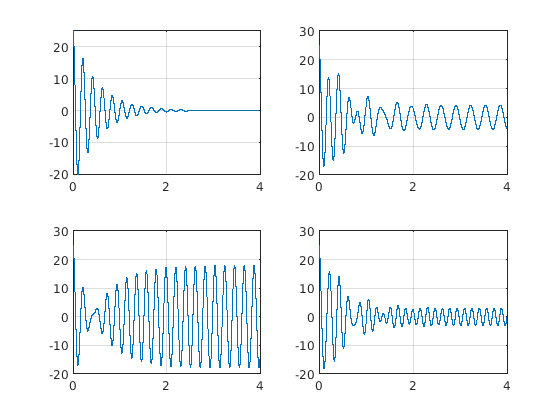

clear all;

t = 0; % s
dt = 10^-4; % s
idx = 1; % counter
simTime = 4; % s

J = 2; % kgm^2
kth = 1800; % Nm/rad
bth = 8; % Nms/rad

th = deg2rad(25);
thDot = 0;

for i = 1:4
    while(t <= simTime)
        if(i == 1)
            M0 = 0;
            omega_p = 0;
        elseif(i == 2)
            M0 = 75;
            omega_p = 20;
        elseif(i == 3)
            M0 = 75;
            omega_p = 30;
        elseif(i == 4)
            M0 = 75;
            omega_p = 40;
        end

        Mk = kth * th;
        Mb = bth * thDot;
        M = M0 * sin(omega_p * t);

        thDotDot = 1/J * (M - Mk - Mb);

        t_plt(idx, i) = t;
        th_plt(idx, i) = th;

        thDot = thDot + thDotDot*dt;
        th = th + thDot*dt;

        t = t + dt;
        idx = idx + 1;
    end
    t = 0;
    idx = 1;
    th = deg2rad(25);
    thDot = 0;
end

figure
for j = 1:4
subplot(2,2,j)
plot(t_plt(:,1), rad2deg(th_plt(:,j)))
grid
end

## Problem 6

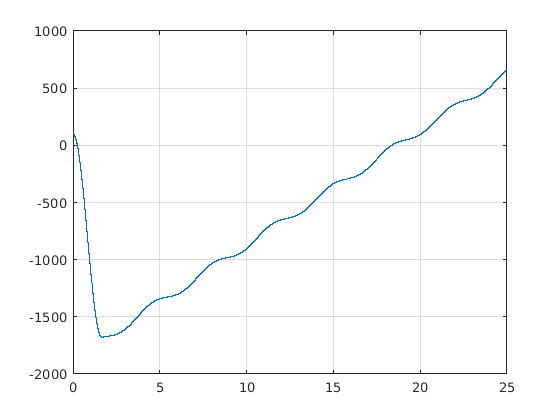

clear all;

t = 0;
dt = 10^-5;
idx = 1;
simTime = 25;

A = 0.2;
B = 0.1;
L0 = 0.1;
k = 1000;
F0 = 500;
v0 = 0.01;
m = 300;
g = 9.81;
theta = deg2rad(30);
x = 0.1;
xDot = 0;

while(t <= simTime)
    x0 = A+B*t;
    
    delta = x0 - x -L0;

    Ffr = F0*tanh(xDot/v0);
    Fg = m*g*sin(theta);
    if(delta*k >= 0)
        Fk = delta*k;
    else
        Fk = 0;
    end
    sumF = Fk-Ffr-Fg;
    xDotDot = sumF/m;

    t_plt(idx) = t;
    x_plt(idx) = x;

    xDot = xDot + xDotDot*dt;
    x = x + xDot*dt;

    t = t + dt;
    idx = idx + 1;
end

figure
plot(t_plt, x_plt*1000)
gridca